# Lab 1 Playing with PID

The transfer function of plant is given as:


$$G\left(s\right)=\frac{e^{-0\ldotp 2\;s} }{s^2 +s}$$


s = tf('s');
G = 1/(s^2+s);
G.iodelay = 0.2;

Remark: note that this system contains a pure time delay. 

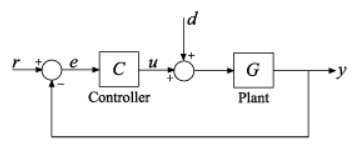

figure 1: feedback structure

We will compute the controller C and consider a negative unitary feedback (figure 1). We will analyse:

- The closed loop step response (r to y). Transfer functions  T=feedback(C*G,1)

- The  perturbation to output step response (d to y). Transfer function P=feedback(G,C)

- The Bode diagram

- The Nyquist diagram

- The sensitivity function. Transfer function S=feedback(1,C*G)

Hint 1: The Matlab Liv editor is nice for many things, except for plotting. For a better use of Bode plots (and other plots) you create external  figures from the command line or enforce external plots with command

>> set(gcf,'Visible','on');

Hint 2: we wil prefer the use of T1=feedback(C*G,1) instead of T2=C*G/(1+C*G). In T2 we have C*G in series with 1/(1+C*G) and Matlab does not cancel extra poles with corresponding zeros, consequently generates virtual non observable and/or non controllable poles...

## 1 Basic control

We first control the system with a pure proportional controler and find the achievable performances.

**Question 1:** what is the gain K1  and the crossover frequency wc if we want a phase margin of 60°?

% On the same diagram we read the gain wher the phase is -120° (-180+60)
wc = 0.46; %rad/s
KdB = -5.97; % We read +5,97dB, means that we must reduce the gain -5,97dB
K1 = 10^(KdB/20);

**Question 2**: what is gain K2  and the phase margin if we want a crossover frequency wc=1 rad/s?

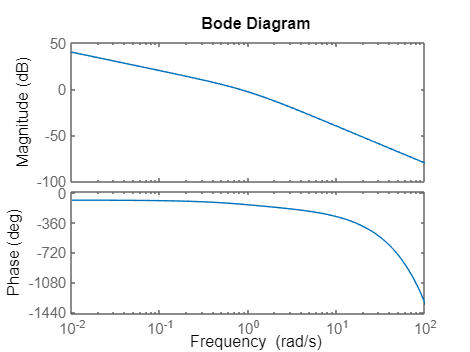

%We plot the Bode diagram, read the gain at w=1 rad/s
bode(G);

KdB=3; % We read -3dB, means that we must  increase the gain +3dB
K2=10^(KdB/20)

K2 = 1.4125

PM = 33 % deg

PM = 33

**Question 3**: compare the step response (r to y) and perturbation rejection (d to y) of both closed loop systems

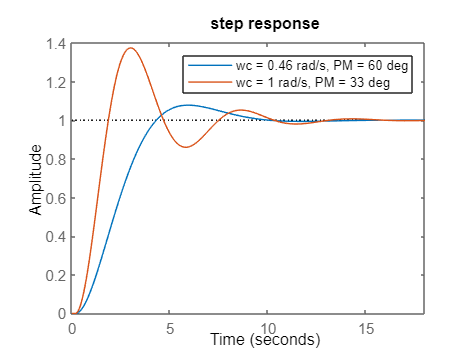

T1 = feedback(K1*G,1);
T2 = feedback(K2*G,1);
P1 = feedback(G,K1);
P2 = feedback(G,K2);
step(T1,T2); 
title('step response');
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg');

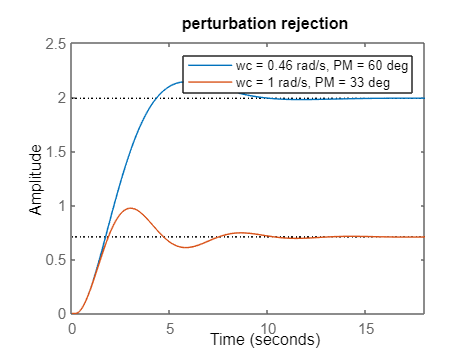

step(P1,P2); 
title('perturbation rejection');
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg');

**Question 4**: compare the closed loop systems in terms of time response, phase margin, overshoot, static perturbation rejection...

Analysis: if we increase the gain:

- the crossover frequency is better

- the system is faster (but this depends on the time criteria: the rising time is better but there are more oscillations, the 2% time response is not that much enhanced...)

- the phase margin is reduced

- the overshoot is greater

- the static error is reduced (rejection of a static perturbation)

**Question 5**: what is the limit value Klim that causes unstability? Answer the quesiton with the root locus diagram (rlocus Matlab function) and a Pade approximation for the delay (pade function)

The root locus cannot easily be plotted because of the time delay. Since this delay is small it can be correctly approximated by a linear transfer functionwitha first order Pade approcimation.

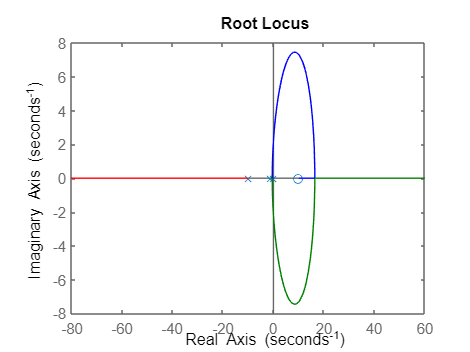

[num,den]=pade(0.2,1);
R=tf(num,den);
Gapprox=R*1/(s^2+s);
rlocus(Gapprox);;

One can read Klim=5.1

## 2 Ziegler Nichols

This method allows to quickly obtain the parameters of a PID that "works in most cases". Although very old fashioned this method is still used in some industrial processes.

Step 1 : find the value Klim of the pure proportional controller that gives limit of closed loop unstability

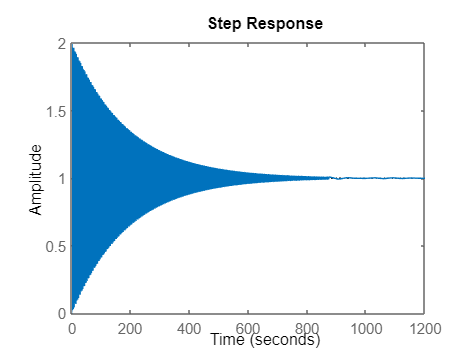

Klim = 5.1;
step(feedback(Klim*G,1)); %iterate Klim tuning until the system is almost unstable, read then pseudo-period Tlim

Tlim=9.73-6.74

Tlim = 2.9900

Step 2: The Ziegler Nichols of a PID are given by the formula below. (Other formulas for a P, PI, PD, see wikipedia)

Kp = 0.6*Klim;
Ki = 1.2*Klim/Tlim;
Kd = 0.075*Klim*Tlim;
Cz = Kp + Ki/s + Kd*s;

**Question 6**: compare the performance with the preformance of the controlelr obtained in question 1

Tz = feedback(Cz*G,1); % Reference to output transfer function
Pz = feedback(G,Cz); % Perturbation to output transfer function
Sz = feedback(1,Cz*G); % Sensitivity function

**Question 7**: What are the step response characteristics ?

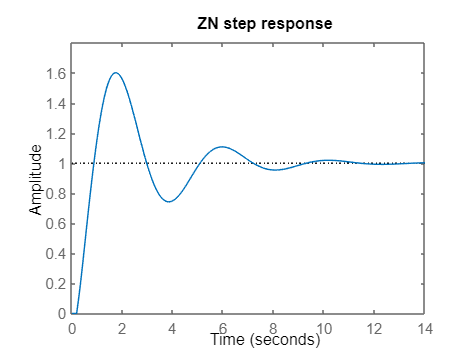

step(Tz);title('ZN step response');

step(Pz);title('ZN perturbation rejection');

Good perturbation rejection (thanks to the integrator), large overshoot

**Question 8**: What is the phase margin? What is the crossover frequency?

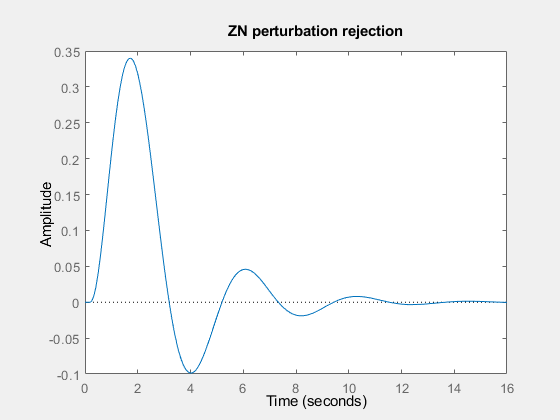

set(gcf,'Visible','on');

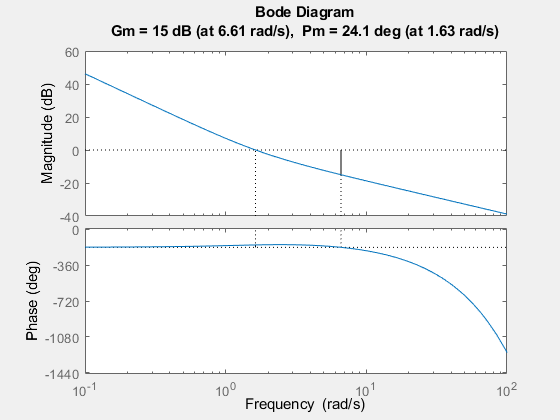

margin(Cz*G)

PM = 24 % deg

PM = 24

wc = 1.63; % rad/s

We can also compare the three controllers;

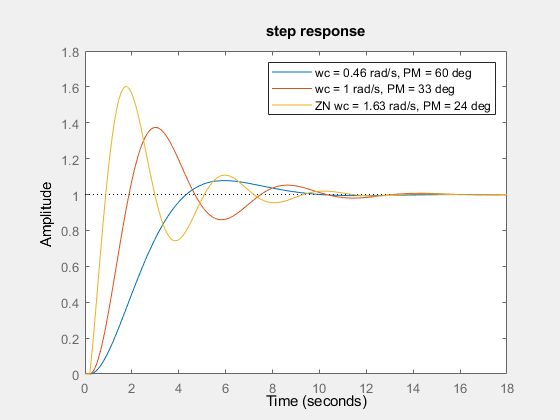

step(T1,T2,Tz);
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg','ZN wc = 1.63 rad/s, PM = 24 deg');
title('step response')

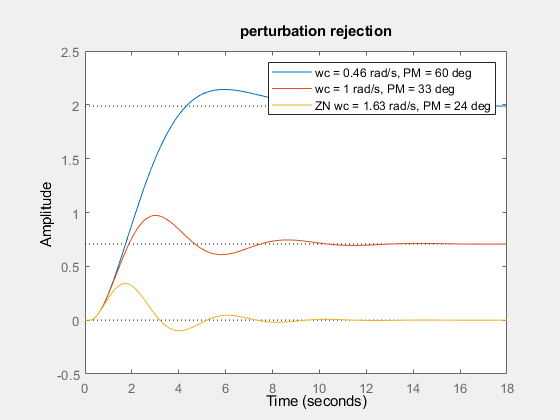

step(P1,P2,Pz);
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg','ZN wc = 1.63 rad/s, PM = 24 deg');
title('perturbation rejection')

## 3 Advanced design, pidtune

The required crossover frequency is wc=1 rad/s and the expected closed loop phase margin is 60°

wc = 1.5;
PM=60

PM = 60

### 3.1 Tuning a PID with pidtune

Have a look to the documentation of pidtune. pidtune performs an optimisation and tries to achieve the required performance goal (default for phase margin is 60°)

opts3 = pidtuneOptions('PhaseMargin',60)

opts3 =   pidtune with properties:

         PhaseMargin: 60
    NumUnstablePoles: 0
         DesignFocus: 'balanced'


[C3,info] = pidtune(G,'PID',wc,opts3)

C3 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.79, Ki = 0.245, Kd = 1.46
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 64.9440


T3 = feedback(G*C3,1);
P3 = feedback(G,C3);

in the **variable** info we see that the optimizer succesfully achieved the required performance . It is not always the case... (Try more demanding crossover frequencies)

**Question 9**: compare the performance of this controller with the ones obtained before

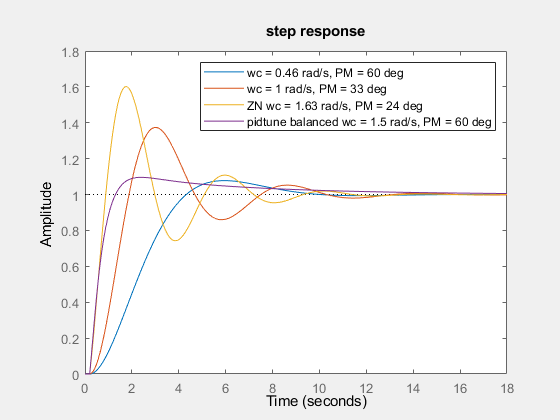

step(T1,T2,Tz,T3);
legend('wc = 0.46 rad/s, PM = 60 deg',...
    'wc = 1 rad/s, PM = 33 deg',...
    'ZN wc = 1.63 rad/s, PM = 24 deg',...
    'pidtune balanced wc = 1.5 rad/s, PM = 60 deg');
title('step response')

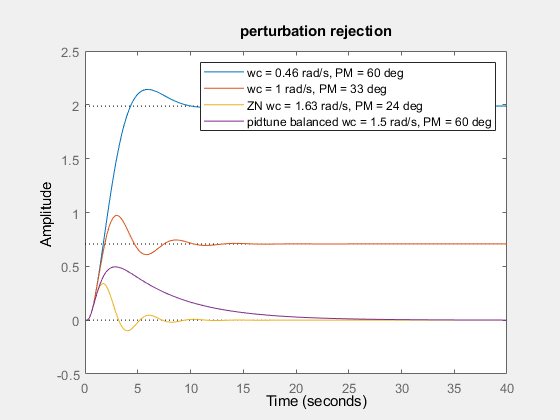

step(P1,P2,Pz,P3);
legend('wc = 0.46 rad/s, PM = 60 deg',...
    'wc = 1 rad/s, PM = 33 deg',...
    'ZN wc = 1.63 rad/s, PM = 24 deg',...
    'pidtune balanced wc = 1.5 rad/s, PM = 60 deg');
title('perturbation rejection')

The controller obtained with pidtune is much better than the pure proportional controllers, and better than the one obtained with the Ziegler-Nichols method, although perturbation rejection is slightly slower.

### 3.2 Modify the phase margins

**Question 10**: design a controller with phase margin 90°

%Phase margin 90°
opts4 = pidtuneOptions('PhaseMargin',90);
[C4,info] = pidtune(G,'PID',wc,opts4)

C4 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.768, Ki = 0.019, Kd = 1.74
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 90.0000


T4 = feedback(G*C4,1);
P4 = feedback(G,C4);

Question 10: design a controller with phase margin 40°, does the algorithm succesfully obtain a controller with this phase margin requirement?

%Phase margin 40°
opts5 = pidtuneOptions('PhaseMargin',40);
[C5,info] = pidtune(G,'PID',wc,opts5)

C5 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.42, Ki = 0.304, Kd = 1.67
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 74.7286


By default the algorithm assume a 'balanced' design. It means that the algorithm try to optumize both reference tracking and perturbation rejection. Here the phase margin is 74 deg instead of the expected 40 deg

### 3.3 Compare DesignFocus

Instead of directly tuning the phase margin one can let the algorithm decide, just setting the DesignFocus parameter:

**Question 11**: compare the performance of the controllers with different DesignFocus parameters

% reference-tracking
opts5 = pidtuneOptions('DesignFocus','reference-tracking');
[C5,info] = pidtune(G,'PID',wc,opts5)

C5 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.61, Ki = 0.0413, Kd = 1.47
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 69.8880


T5 = feedback(G*C5,1);
P5 = feedback(G,C5);
S5 = feedback(1,G*C5);
% balanced
opts6 = pidtuneOptions('DesignFocus','balanced');
[C6,info] = pidtune(G,'PID',wc,opts6)

C6 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.79, Ki = 0.245, Kd = 1.46
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 64.9440


T6 = feedback(G*C6,1);
P6 = feedback(G,C6);
S6 = feedback(1,G*C6);
% disturbance-rejection
opts7 = pidtuneOptions('DesignFocus','disturbance-rejection');
[C7,info] = pidtune(G,'PID',wc,opts7)

C7 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.96, Ki = 0.632, Kd = 1.52
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 60.0000


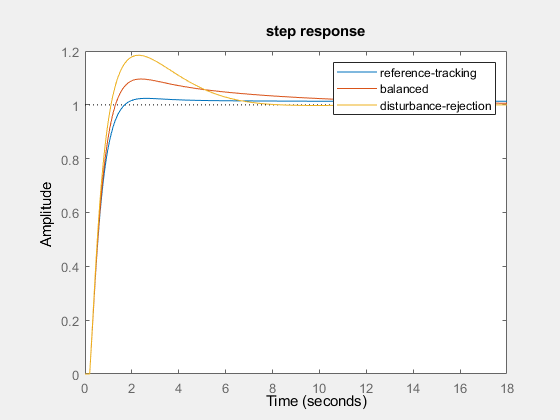

T7 = feedback(G*C7,1);
P7 = feedback(G,C7);
S7 = feedback(1,G*C7);
step(T5,T6,T7);
legend('reference-tracking',...
    'balanced',...
    'disturbance-rejection');
title('step response')

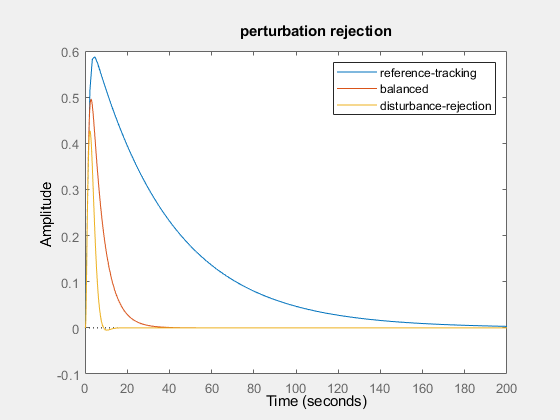

step(P5,P6,P7);
legend('reference-tracking',...
    'balanced',...
    'disturbance-rejection');
title('perturbation rejection')


% didn't understand the reasoning

Conclusion: there is no miracle... Even if The optimization algorithm takes full advantage of the three degrees of freedom (or 4 for PIDF or more for 2dof PIDs) there will be a tradeoff between time domain performance perturbatin rejection. Enhancing perturbation rejection means increasing low frequency gain, and consequenty reduce phase margin... 

## 4 More stuff

Look at stability margin on Nyquist plot (zoom near (-1,0)

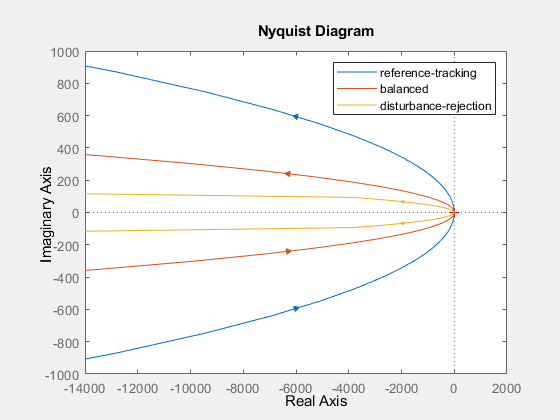

set(gcf,'Visible','on');
nyquist(C5*G,C6*G,C7*G);
legend('reference-tracking',...
    'balanced',...
    'disturbance-rejection');

Discuss sensitivity function. The higher is the max of S the worse is the robustness

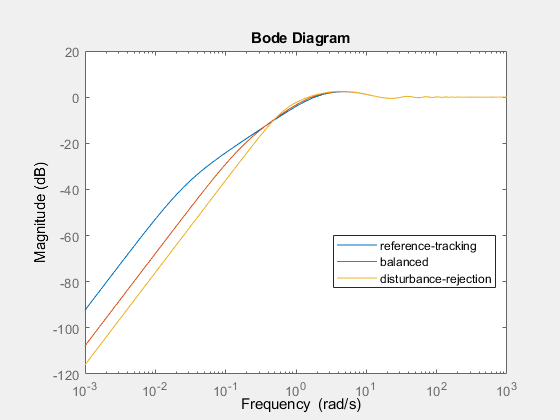

h = bodeplot(S5,S6,S7);
setoptions(h,'PhaseVisible','off');
legend('reference-tracking',...
    'balanced',...
    'disturbance-rejection');

Discuss low frequency gain (perturbation rejection) on T bode diagrams